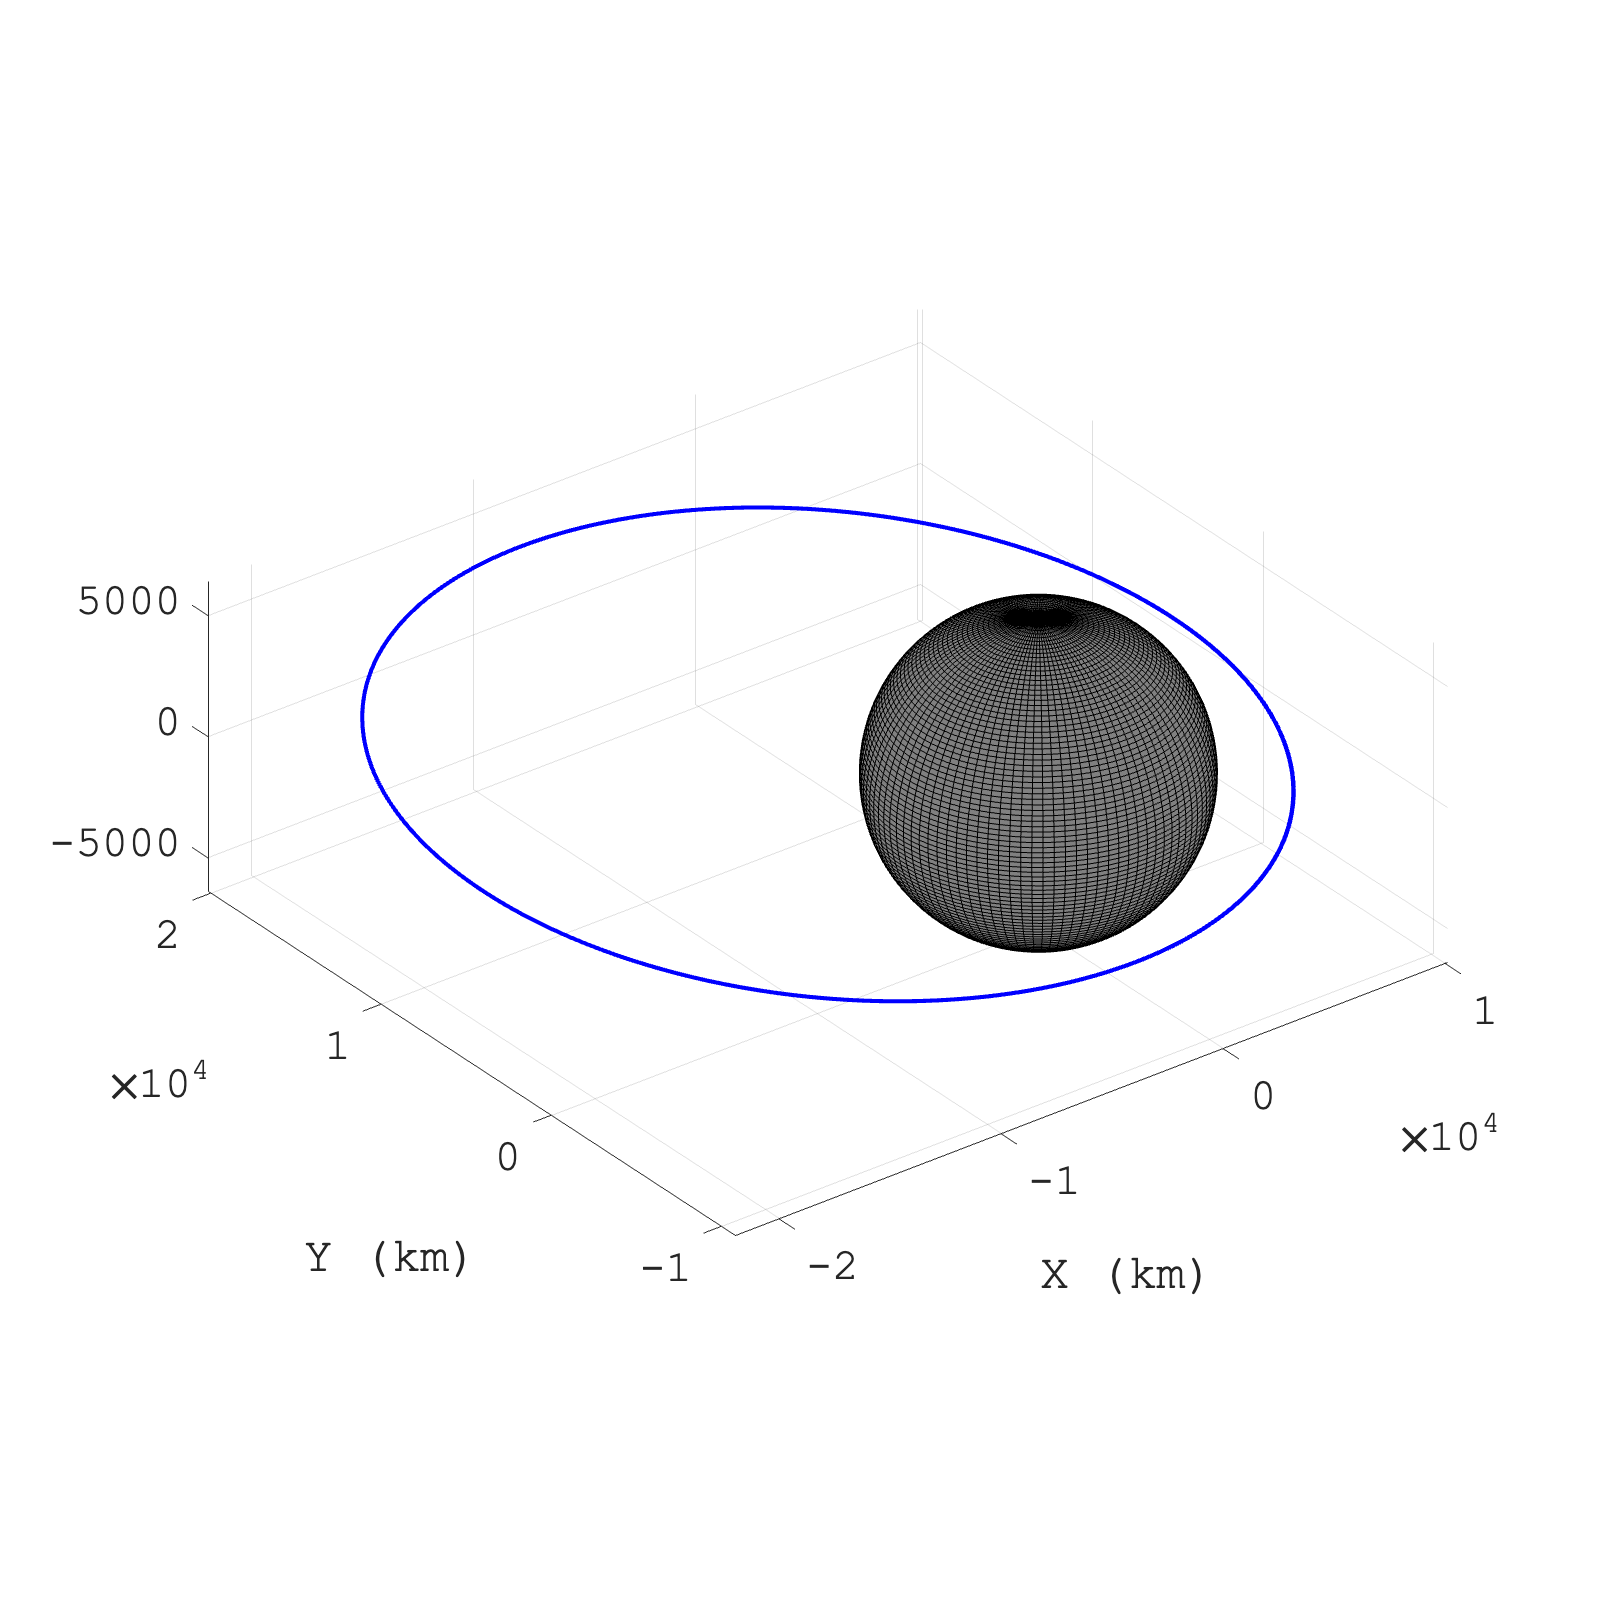

global mu R;

mu = 398600;
R = 6400;

% Inputs
x = 10000;
y = 1000;
z = 0;
xdot = 1;
ydot = sqrt(mu/x)+1;
zdot = 1;

tspan = linspace(0,48*3600,1.0e3);

options = odeset('RelTol',1.0e-6,'InitialStep',1.0e-6,'AbsTol',1.0e-6);

[t,X] = ode45(@ode_func,tspan,[x,y,z,xdot,ydot,zdot],options);

fig = figure();
set(fig,'position',[0 0 1200 1200]);
plot3(X(:,1),X(:,2),X(:,3),'b','linewidth',2);
hold on;
[x,y,z] = sphere(100);
x = x*R;
y = y*R;
z = z*R;
surf(x,y,z,'EdgeColor','k','FaceColor','#808080');
axis equal;
grid on;
set(gcf,'Color','w');
set(gca,'Color','w');
set(gca,'FontSize',22,'FontName','Courier New');
xlabel('X (km)');
ylabel('Y (km)');
hold off;

function Xdot = ode_func(~,X)
global mu

x = X(1);
y = X(2);
z = X(3);
xdot = X(4);
ydot = X(5);
zdot = X(6);

r=sqrt(x^2+y^2+z^2);

Xdot(1,1) = xdot;
Xdot(2,1) = ydot;
Xdot(3,1) = zdot;
Xdot(4,1) = -mu * x / r^3;
Xdot(5,1) = -mu * y / r^3;
Xdot(6,1) = -mu * z / r^3;
end